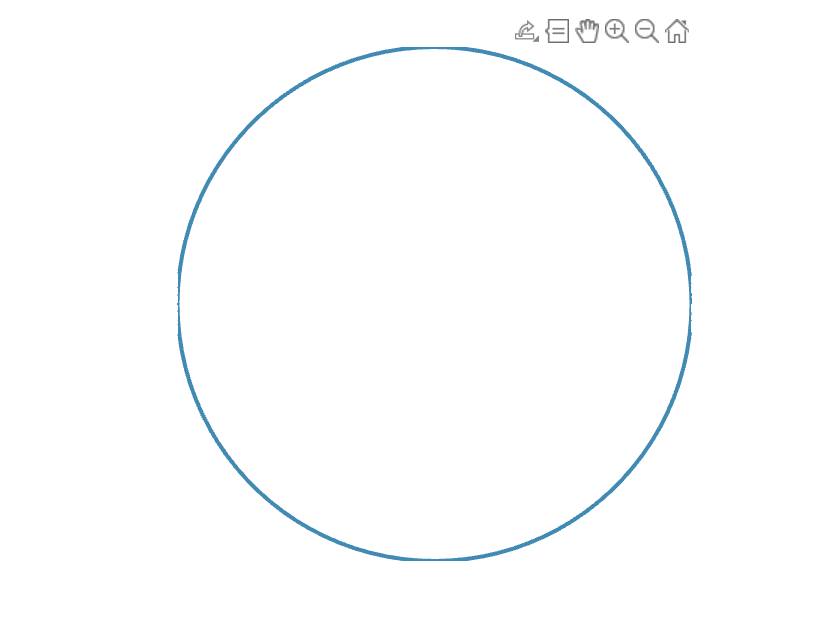

col = [65, 138, 179]/255;

dnum = 101;
t = linspace(0, 1, dnum);
x = cos(2*pi*t); y = sin(2*pi*t);

figure()
ax = gca;
plot(ax, x, y, '-', 'LineWidth', 2, 'Color', col);
set(ax, 'XTick', []); set(ax, 'YTick', []); set(ax, 'Visible', 'off'); box(ax, "off"); axis equal square;

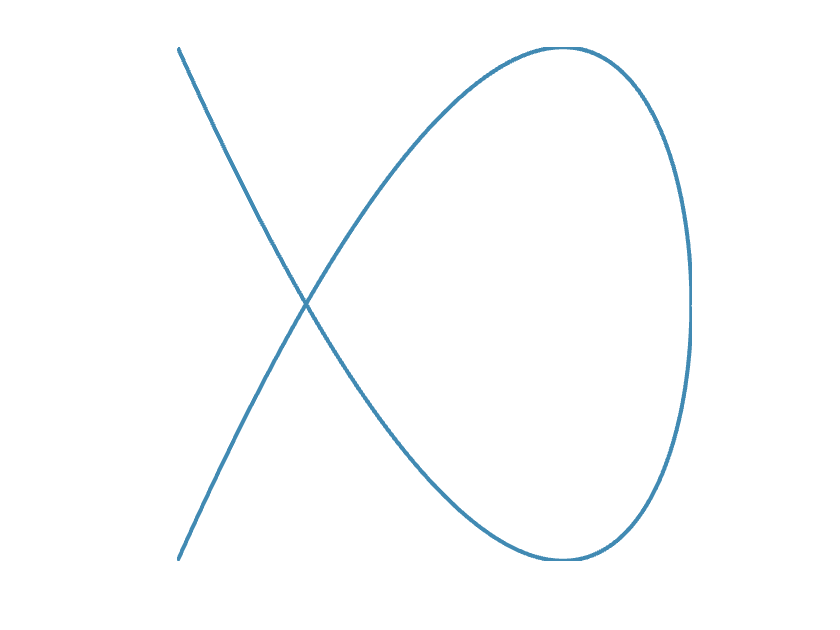


t = linspace(0, 2, 2*dnum);
x = cos(2*pi*t); y = sin(1.5*2*pi*t);

figure()
ax = gca;
plot(ax, x, y, '-', 'LineWidth', 2, 'Color', col);
set(ax, 'XTick', []); set(ax, 'YTick', []); set(ax, 'Visible', 'off'); box(ax, "off"); axis equal square;

addpath 'Live Scripts'\ 'Data'\ 'Utility Functions'\;
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
if exist('Data\case_1_kinematicMobility.mat', "file")
    load('Data\case_1_kinematicMobility.mat');
else
    error(['ERROR! The motion planning kinematics data file is needed. ' ...
        'Create one in the "se2_toyproblems_case_1.mlx" (last section).']);
end

stanceNow = FRHLstance; % choose a stance phase % FRHLstance % FLHRstance
F_bounds = stanceNow.F_bounds; % obtain the allowed F-limits
F_bounds_full = [stanceNow.F_inf, stanceNow.F_sup]; % full F-limits
F_fxn = stanceNow.F_fxn;

aa = 1; ll = 1; 
ank = pi/2; % some default vars
% ... ank is the symmetric angle limit amplitude for all limbs

aInf = FRHLstance.aInf

aInf =    -2.3562   -2.3562


aSup = FRHLstance.aSup 

aSup =     0.7854    0.7854


randNumGen = @() ank*(2*rand([1, 2], "double") - 1) % generate a random reference point

randNumGen = function_handle with value:
    @()ank*(2*rand([1,2],"double")-1)


r = randNumGen()

r =     0.9887    1.2748


% r = zeros(1, 2) % using the origin
r = pi/4*ones(1, 2) % using the sup(F) singularity

r =     0.7854    0.7854



% define a function to evaluate the F-value along a line
function fVal = FalongLine(aa, ll, F_fxn, refPt, unitPhasor, aValue)
    pt = returnPtAlongLineFromIC(refPt, unitPhasor, aValue)';
    fVal = F_fxn(aa, ll, pt(1), pt(2));
end
F_fxn_opt = @FalongLine;

Check if "aInf" is closer to "aSup" or "r" is closer to "aSup".

% arrange the points a certain way
pts = {aInf, r, aSup};
% iterate over each ordered pair and get the intervals of interest
slipAxisPoints = [];
for i = 1:(numel(pts)-1)
    % get a vector from point 1 (tail of arrow above) to point 2 (head)
    vec = pts{i+1} - pts{i};
    % ensure that this vector is not too small
    % ... for now I'm setting the threshold to 1% of the allowable
    % ... symmetric range that we have assumed
    % ... if the threshold is not cleared, use the next vector or the
    % ... previous vector
    if norm(vec) - 2*ank*1e-2 < 0
        switch i
            case 1
                vec = pts{i+2} - pts{i+1};
            case 2
                vec = pts{i} - pts{i-1};
        end
    end
    % get the phasor info
    phasorAngle1 = atan2(vec(2), vec(1));
    % get the x and y components for the line generator
    delX = cos(phasorAngle1);
    delY = sin(phasorAngle1);
    % find the a value at which the next point occurs
    aTemp = vec./[delX, delY]; 
    aTemp(isinf(aTemp)) = nan; % nan INF values
    aPtNext = mean(aTemp, "omitnan"); % omit nans
    % current pt is at 0
    aPtCurr = 0;
    % find the intersection to actual shape space bounds
    aAnkX = (ank*[-1, 1] - repmat(pts{i}(1), 1, 2))/delX;
    aAnkX(isinf(aAnkX)) = nan; % NaNize
    aAnkY = (ank*[-1, 1] - repmat(pts{i}(2), 1, 2))/delY;
    aAnkY(isinf(aAnkY)) = nan; % NaNize
    % accessible shape space and allowable points
    % ... find the "ank" on the boundary
    aAnk = [aAnkX, aAnkY];
    % ... get the points on the boundary
    ptAnk = returnPtAlongLineFromIC(pts{i}, ...
                            [delX, delY], ...
                            aAnk);
    validAnk = all...
        (ptAnk >= -ank-0.01*2*ank ...
       & ptAnk <= +ank+0.01*2*ank, 1);
    aAnk = aAnk(validAnk);
    switch i
        case 1 % if the next point is the refernce point
            aAnk = aAnk(aAnk < aPtNext);
        case 2 % if the current point is the reference point
            aAnk = aAnk(aAnk > aPtCurr);
    end
    % ... if the are still multiple points, take the mean to get a single
    % ... point
    aAnk = mean(aAnk);
    % ... define a list and sort the points
    aList = [aPtNext, aPtCurr, aAnk]; % initialize the list
    switch i
        case 1 % inf(F) singularity to reference
            aList = sort( aList(aList >= aAnk & aList <= aPtNext) );
        case 2 % reference to sup(F) singularity
            aList = sort( aList(aList >= aPtCurr & aList <= aAnk) );
    end
    % ... get the points along the limits
    ptList = returnPtAlongLineFromIC(pts{i}, [delX, delY], aList);
    ptList = mat2cell(ptList, size(ptList, 1), ones(1, size(ptList, 2)));
    % iterate over the number of points and do stuff
    validFlagList = false(1, numel(ptList));
    for j = 1:numel(ptList)
        % current point
        ptNow = ptList{j};
        % evaluate the F-value at these points and see if the value is
        % being violated
        FvalNow = F_fxn(aa, ll, ptNow(1), ptNow(2));
        % check if any of the points are violating the condition, if
        % neither are, then there is no weird point in between
        % write an optimizer to check if there is a lower bound or an
        % upper bound
        if FvalNow >= F_bounds(1) && FvalNow <= F_bounds(2)
            validFlagList(j) = true;
        end
    end
    validNum = nnz(validFlagList);
    % based on the number of points we shall do the following
    % ... if two points it is relatively straightforward
    % ... else, if it is three points, then we need to iterate over the two
    % ... branches that occur and obtain the solutions separately to see if
    % ... there is a F-value violation
    switch numel(aList)
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        case 2 % ONE branch
            % if both points are valid generate a normal branch
            switch validNum
                case 1
                    % only one of the points is valid, find the point where
                    % the bounds are violated, then it is that point to the
                    % valid point
                    [aLowViolation, fValViolation] = ...
                    fmincon( @(a) abs(F_bounds(1) - ...
                        F_fxn_opt(aa, ll, F_fxn, pts{i}, [delX, delY], a)), ...
                        aList(1), ...
                        [], [], [], [], ...
                        aList(1), aList(2), ...
                        [], ...
                        optimoptions("fmincon", "Display", "off") ...
                            );
                    if fValViolation < 1e-5*diff(F_bounds_full)
                        aViolation = aLowViolation;
                    else
                        [aHighViolation, fValViolation] = ...
                        fmincon( @(a) abs(F_bounds(2) - ...
                            F_fxn_opt(aa, ll, F_fxn, pts{i}, [delX, delY], a)), ...
                            aList(1), ...
                            [], [], [], [], ...
                            aList(1), aList(2), ...
                            [], ...
                            optimoptions("fmincon", "Display", "off") ...
                                );
                        if fValViolation < 1e-5*diff(F_bounds_full)
                            aViolation = aHighViolation;
                        end
                    end
                    % if the violation point is valid, then use
                    if exist("aViolation", "var")
                        [aList, sortIdx] = sort([aList, aViolation]);
                        validFlagList = [validFlagList, true];
                        validFlagList = validFlagList(sortIdx); % obtain the locations
                        aList = aList( ...
                            find(validFlagList, 1, "first"):... % starting point
                            find(validFlagList, 1, "last")... % end point
                                        ); % obtain the valid branch
                        slipAxisPoints{end+1} = ...
                            returnPtAlongLineFromIC(...
                                    pts{i}, [delX, delY], ...
                                    [aList(1), aList(2)]...
                                                    )';
                        clear aViolation;
                    else
                        error("ERROR! Not sure what's going on here.");
                    end
                case 2
                    % both points are valid, obtain the slipping axis
                    slipAxisPoints{end+1} = ...
                        returnPtAlongLineFromIC(...
                                pts{i}, [delX, delY], ...
                                [aList(1), aList(2)]...
                                                )';
                otherwise
                    error(['ERROR! The reference point pts{2} should always be valid. ' ...
                        'Even if it is, do not place it closer to the corners of the ' ...
                        'valid shape space.']);
            end
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        case 3 % TWO branches
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            % get the working indices
            switch validNum
                case 1
                    workingIdx = find(validFlagList, 1, "first");
                    notWorkingIdx = find(~validFlagList, 2, "first");
                    % there can only be one branch here
                    [aLowViolation, fValViolation] = ...
                    fmincon( @(a) abs(F_bounds(1) - ...
                        F_fxn_opt(aa, ll, F_fxn, pts{i}, [delX, delY], a)), ...
                        aList(2), ...
                        [], [], [], [], ...
                        aList(1), aList(3), ...
                        [], ...
                        optimoptions("fmincon", "Display", "off") ...
                            );
                    if fValViolation < 1e-5*diff(F_bounds_full)
                        aViolation = aLowViolation;
                    else
                        [aHighViolation, fValViolation] = ...
                        fmincon( @(a) abs(F_bounds(2) - ...
                            F_fxn_opt(aa, ll, F_fxn, pts{i}, [delX, delY], a)), ...
                            aList(2), ...
                            [], [], [], [], ...
                            aList(1), aList(3), ...
                            [], ...
                            optimoptions("fmincon", "Display", "off") ...
                                );
                        if fValViolation < 1e-5*diff(F_bounds_full)
                            aViolation = aHighViolation;
                        end
                    end
                    if exist("aViolation", "var")
                        [aList, sortIdx] = sort([aList(workingIdx), aViolation]);
                        validFlagList = [validFlagList, true];
                        validFlagList = validFlagList(sortIdx);
                        slipAxisPoints{end+1} = ...
                            returnPtAlongLineFromIC(...
                                    pts{i}, [delX, delY], ...
                                    [aList(1), aList(2)]...
                                                    )';
                        clear aViolation;
                    else
                        error("ERROR! Not sure what's going on here.");
                    end
                case 2
                    workingIdx = find(validFlagList, 2, "first");
                    notWorkingIdx = find(~validFlagList, 1, "first");
                    % see how many branches are there, and then do it accordingly
                    switch any(notWorkingIdx == 2)
                        case 1 % 2 branches
                            for j = 1:(numel(validFlagList)-1)
                                aSubList = aList(j:j+1);
                                validFlagSubList = validFlagList(j:j+1);
                                [aLowViolation, fValViolation] = ...
                                fmincon( @(a) abs(F_bounds(1) - ...
                                    F_fxn_opt(aa, ll, F_fxn, pts{i}, [delX, delY], a)), ...
                                    aSubList(1), ...
                                    [], [], [], [], ...
                                    aSubList(1), aSubList(2), ...
                                    [], ...
                                    optimoptions("fmincon", "Display", "off") ...
                                        );
                                if fValViolation < 1e-5*diff(F_bounds_full) % (0.001%) of the full F-range
                                    aViolation = aLowViolation;
                                else
                                    [aHighViolation, fValViolation] = ...
                                    fmincon( @(a) abs(F_bounds(2) - ...
                                        F_fxn_opt(aa, ll, F_fxn, pts{i}, [delX, delY], a)), ...
                                        aSubList(1), ...
                                        [], [], [], [], ...
                                        aSubList(1), aSubList(2), ...
                                        [], ...
                                        optimoptions("fmincon", "Display", "off") ...
                                            );
                                    if fValViolation < 1e-5*diff(F_bounds_full)
                                        aViolation = aHighViolation;
                                    end
                                end
                                if exist("aViolation", "var")
                                    [aSubList, sortIdx] = sort([aSubList(workingIdx(j)-j+1), aViolation]);
                                    validFlagSubList = [validFlagSubList(workingIdx(j)-j+1), true];
                                    validFlagSubList = validFlagSubList(sortIdx);
                                    slipAxisPoints{end+1} = ...
                                        returnPtAlongLineFromIC(...
                                                pts{i}, [delX, delY], ...
                                                [aSubList(1), aSubList(2)]...
                                                                )';
                                    clear aViolation;
                                else
                                    error("ERROR! Not sure what's going on here.");
                                end
                            end
                        case 0 % 1 branch
                            endWorkingIdx = workingIdx(workingIdx == 1 || workingIdx == 3);
                            aEndWorkingPt = aList(endWorkingIdx);
                            validFlagEndWorking = validFlagList(endWorkingIdx);
                            [aLowViolation, fValViolation] = ...
                            fmincon( @(a) abs(F_bounds(1) - ...
                                F_fxn_opt(aa, ll, F_fxn, pts{i}, [delX, delY], a)), ...
                                aList(2), ...
                                [], [], [], [], ...
                                aList(1), aList(3), ...
                                [], ...
                                optimoptions("fmincon", "Display", "off") ...
                                    );
                            if fValViolation < 1e-5*diff(F_bounds_full)
                                aViolation = aLowViolation;
                            else
                                [aHighViolation, fValViolation] = ...
                                fmincon( @(a) abs(F_bounds(2) - ...
                                    F_fxn_opt(aa, ll, F_fxn, pts{i}, [delX, delY], a)), ...
                                    aList(2), ...
                                    [], [], [], [], ...
                                    aList(1), aList(3), ...
                                    [], ...
                                    optimoptions("fmincon", "Display", "off") ...
                                        );
                                if fValViolation < 1e-5*diff(F_bounds_full)
                                    aViolation = aHighViolation;
                                end
                            end
                            if exist("aViolation", "var")
                                [aList, sortIdx] = sort([aEndWorkingPt, aViolation]);
                                validFlagList = [validFlagList, true];
                                validFlagList = validFlagList(sortIdx);
                                slipAxisPoints{end+1} = ...
                                    returnPtAlongLineFromIC(...
                                            pts{i}, [delX, delY], ...
                                            [aList(1), aList(2)]...
                                                            )';
                                clear aViolation;
                            else
                                error("ERROR! Not sure what's going on here.");
                            end
                        otherwise
                            error('ERROR! You should not be here.');
                    end
                otherwise
                    error('ERROR! You really should not be here.');
            end
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
end

Let's plot and make sure these slip axis points work just fine.

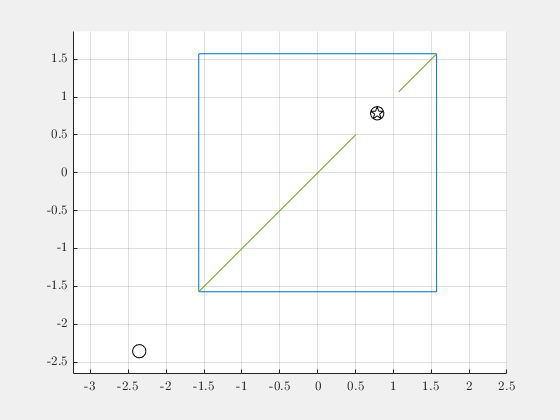

% ... define the allowable shape space bounds as a quiver plot
xBounds = ank*[-1, 1, 1, -1]; yBounds = circshift(xBounds, 1);
xBounds = [xBounds, xBounds(:, 1)]; yBounds = [yBounds, yBounds(:, 1)];
boundsDiff = diff([xBounds; yBounds], 1, 2);
uBounds = boundsDiff(1, :);
vBounds = boundsDiff(2, :);
xBounds = xBounds(:, 1:end-1); yBounds = yBounds(:, 1:end-1);

% ... define the slipping axis as a quiver plot
xSlip = []; ySlip = []; uSlip = []; vSlip = [];
for i = 1:numel(slipAxisPoints)
    diffNow = diff(slipAxisPoints{i}, 1, 1);
    xSlip = [xSlip, slipAxisPoints{i}(1, 1)];
    ySlip = [ySlip, slipAxisPoints{i}(1, 2)];
    uSlip = [uSlip, diffNow(1)];
    vSlip = [vSlip, diffNow(2)];
end

figure('Visible', 'on'); ax = gca; 
axis(ax, [-ank, ank, -ank, ank], "equal", "padded"); 
hold(ax, "on"); grid(ax, "on");
quiver(ax, xBounds, yBounds, uBounds, vBounds, ...
    "AutoScale", "off", "LineWidth", 0.5, ...
    "ShowArrowHead", "off");
scatter(ax, pts{1}(1), pts{1}(2), 100, 'k'); % singularity at infimum
scatter(ax, pts{2}(1), pts{2}(2), 100, 'k', 'Marker', 'pentagram'); % reference
scatter(ax, pts{3}(1), pts{3}(2), 100, 'k'); % singularity at supremum
quiver(ax, xSlip, ySlip, uSlip, vSlip, ...
    "AutoScale", "off", "LineWidth", 0.5, ...
    "ShowArrowHead", "off");